# p02

## clear history

clearvars all;
clc;

## part a

% given
I = diag([10; 20; 30])

I =     10     0     0
     0    20     0
     0     0    30


omega0_deg = [10; 0; 30];
omega0 = deg2rad(omega0_deg);

% solution
H0 = I*omega0;
H0_mag = norm(H0);
T0 = 1/2*transpose(omega0)*I*omega0;

% display
H0_mag, T0

H0_mag = 15.8046

T0 = 4.2646

## part b

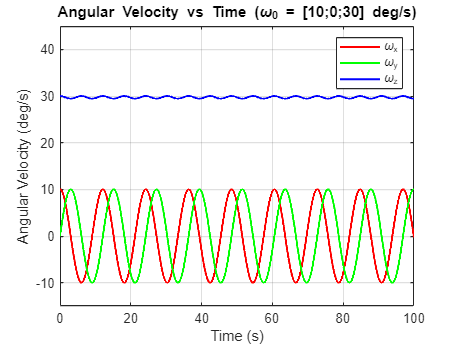

% solution
dwdt = @(t, omega) inv(I)*(-cross(omega, I*omega));
tspan = [0, 100];
oopts = odeset('RelTol',1e-9,'AbsTol',1e-9);

[t1, w1] = ode45(dwdt, tspan, omega0, oopts);
w1_deg = rad2deg(w1);

% plot
fig = figure;
plot(t1, w1_deg(:,1), 'r', t1, w1_deg(:,2), 'g', t1, w1_deg(:,3), 'b', 'LineWidth', 1.5);
title('Angular Velocity vs Time (\omega_0 = [10;0;30] deg/s)');
legend('\omega_x','\omega_y','\omega_z');
xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
ylim([-15 45]);
grid on;

% save
saveas(fig, "./images/s02b.png");

## part c

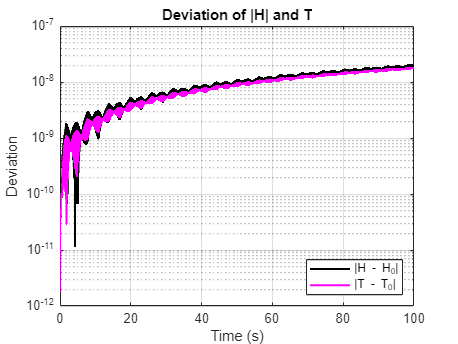

% solution
H1 = transpose(I * transpose(w1));
H1_mag = sqrt(sum(H1.^2,2));
T1 = 1/2*sum(w1.*H1, 2);

dH = abs(H1_mag-H0_mag);
dT = abs(T1-T0);

% plot
fig = figure;
plot(t1, dH, 'k', t1, dT, 'm', 'LineWidth', 1.5);
title('Deviation of |H| and T');
legend('|H - H_0|','|T - T_0|', 'Location', 'southeast');
xlabel('Time (s)');
ylabel('Deviation');
yscale("log");
grid on;

% save
saveas(fig, "./images/s02c.png");

I believe my code is working, as the both the angular momentum deviation and kinetic energy deviation are extremely minimal, being on the order of $10^{-8}$.

## part d

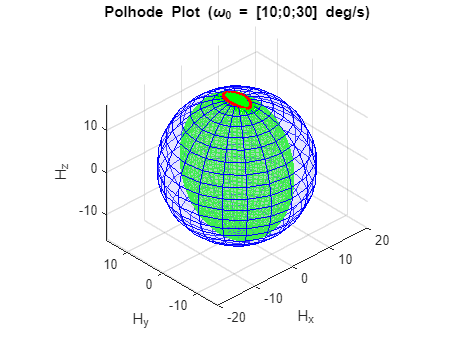

% solution
[Xs, Ys, Zs] = sphere(20);
Xs = H0_mag*Xs;
Ys = H0_mag*Ys;
Zs = H0_mag*Zs;

radii = sqrt(2*T0.*diag(I));
[Xe, Ye, Ze] = ellipsoid(0,0,0, radii(1), radii(2), radii(3), 60);

% plot
fig = figure;
hold on;
% sphere
surf(Xs, Ys, Zs, 'FaceAlpha',0.3, 'EdgeColor','b', 'FaceColor', [0.8 0.8 1]);
% ellipsoid
surf(Xe, Ye, Ze, 'FaceAlpha',0.3, 'EdgeColor','g', 'FaceColor', [0.2 0.8 0.2]);
% polhode points (body-fixed H)
plot3(H1(:,1), H1(:,2), H1(:,3), '.r', 'MarkerSize', 5);
title('Polhode Plot (\omega_0 = [10;0;30] deg/s)');
xlabel('H_x');
ylabel('H_y');
zlabel('H_z');
axis equal;
grid on;
view([-43.3 33.8])
hold off;

% save
saveas(fig, "./images/s02d.png");

## part e

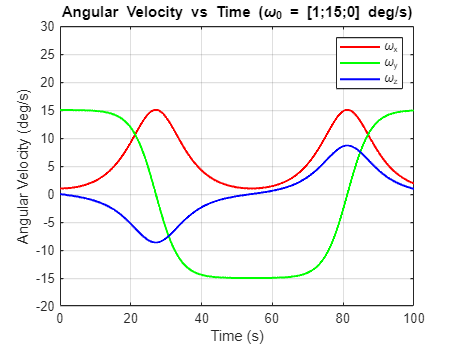

% solution
omega2_deg = [1; 15; 0];
omega2 = deg2rad(omega2_deg);
[t2, w2] = ode45(dwdt, tspan, omega2, oopts);
w2_deg = rad2deg(w2);

% plot
fig = figure;
plot(t2, w2_deg(:,1), 'r', t2, w2_deg(:,2), 'g', t2, w2_deg(:,3), 'b', 'LineWidth', 1.5);
title('Angular Velocity vs Time (\omega_0 = [1;15;0] deg/s)');
legend('\omega_x','\omega_y','\omega_z');
xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
ylim([-20 30]);
grid on;

% save
saveas(fig, "./images/s02e.png");

## part f

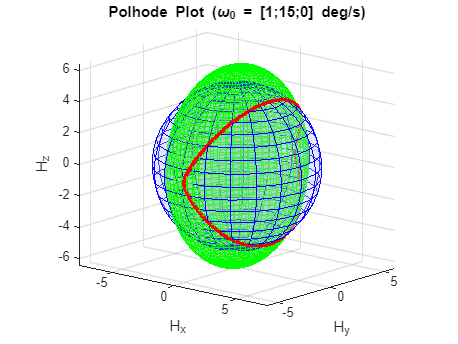

% solution
H2_0 = I*omega2;
H2_0_mag = norm(H2_0);
T2_0 = 1/2*transpose(omega2)*I*omega2;

H2 = transpose(I*transpose(w2));
H2_mag = sqrt(sum(H2.^2,2));
T2 = 1/2*sum(w2.*H2, 2);

[Xs, Ys, Zs] = sphere(20);
Xs = H2_0_mag*Xs;
Ys = H2_0_mag*Ys;
Zs = H2_0_mag*Zs;

radii = sqrt(2*T2_0.*diag(I));
[Xe, Ye, Ze] = ellipsoid(0,0,0, radii(1), radii(2), radii(3), 60);

% plot
fig = figure;
hold on;
% sphere
surf(Xs, Ys, Zs, 'FaceAlpha',0.3, 'EdgeColor','b', 'FaceColor', [0.8 0.8 1]);
% ellipsoid
surf(Xe, Ye, Ze, 'FaceAlpha',0.3, 'EdgeColor','g', 'FaceColor', [0.2 0.8 0.2]);
% polhode points (body-fixed H)
plot3(H2(:,1), H2(:,2), H2(:,3), '.r', 'MarkerSize', 5);
title('Polhode Plot (\omega_0 = [1;15;0] deg/s)');
xlabel('H_x');
ylabel('H_y');
zlabel('H_z');
axis equal;
grid on;
view([40.6 14.7]);
hold off;

% save
saveas(fig, "./images/s02f.png");

The spacecraft in part b and d has a much higher kinetic energy in the Z axis than in the X and Y axes, and as well varies each axis in only small oscillations. This is far different from the spacecraft in e and f, who has far more energy-variance within each axis, as well as having its overall spread be much closer together. These two differences result in the Polhode plot of the first spacecraft being confined to a small area high in the positive Z axis, while the second spacecraft's plot ventures all over the place.